# Augmented Reality Matlab Capstone

## Load Picture or Video Frame of Floor Plan

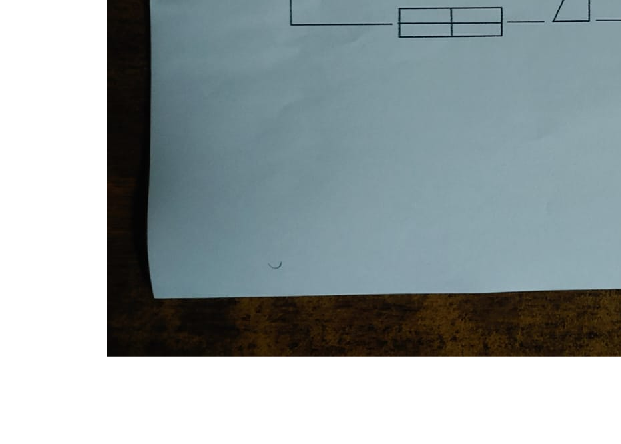

% Paths to folders containing Helper Functions
addpath("Functions\Doors\");
addpath("Functions\Windows\");
addpath("Functions\");
addpath("Pictures\");

% Image Path
imagePath = 'sample_floor_plan19.jpeg';
img = py.cv2.imread(imagePath); % Read image file using  python
I = imread(imagePath); % Read image file using matlab
imshow(I);

## Get Camera Intrinsics

data = load('calibrationSession1.mat');
intrinsics = cameraParams1.Intrinsics;

## Estimate Pose

tagSize = 20; % in mm
tagFamily = "tag36h11";
[~, ~, tagPose] = readAprilTag(I, tagFamily, intrinsics, tagSize);

## Display The Axis

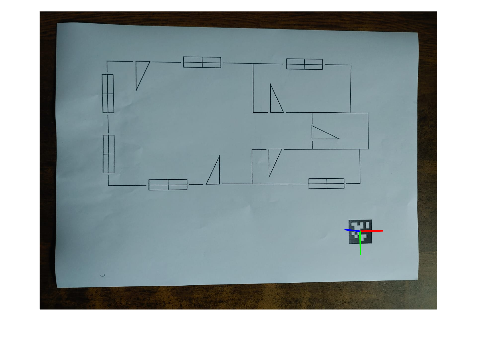

annotatedImage = helperInsertXYZAxes(I, tagPose, intrinsics, tagSize);
figure
imshow(annotatedImage)

## Rotate Axis

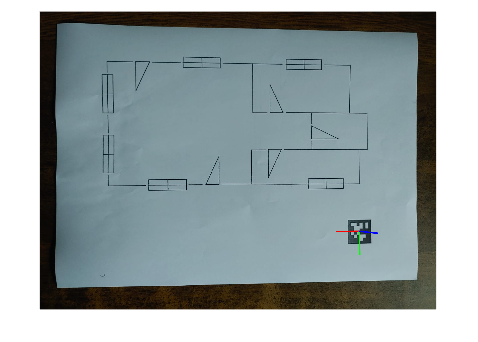

rotationAngles = [0 180 0];
tform = rigidtform3d(rotationAngles, [0 0 0]);
updatedR = tagPose.R * tform.R;
tagPose = rigidtform3d(updatedR, tagPose.Translation);


annotatedImage = helperInsertXYZAxes(I, tagPose, intrinsics, tagSize);
figure
imshow(annotatedImage)

## Document Detection

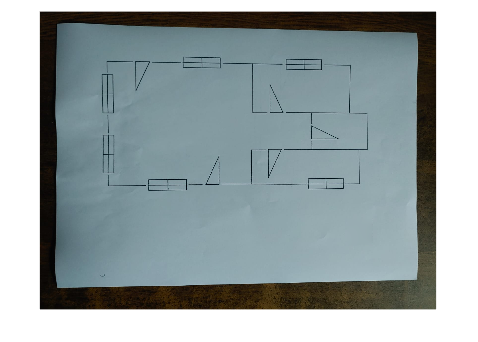

%--- This work flow aims to remove the surrounding background ---%
% --- Step1: Mask Out April Tag ---%
[cubeWidth, cubeHeight, cubeDepth] = deal(tagSize);

vertices = [ cubeWidth/2 -cubeHeight/2 0; 
             cubeWidth/2  cubeHeight/2 0;
            -cubeWidth/2  cubeHeight/2 0;
            -cubeWidth/2 -cubeHeight/2 0]; % World coordinates of april tag

projectedVertices = world2img(vertices, tagPose, intrinsics); % Image coordinates of april tagminX = min(projectedVertices(:,1));

minX = min(projectedVertices(:,1));
maxX = max(projectedVertices(:,1));
minY = min(projectedVertices(:,2));
maxY = max(projectedVertices(:,2));

bbox = [minX, minY, maxX-minX, maxY-minY];  % [x, y, width, height]

maskedImage = I;  % Initialize maskedImage with the original image
% Scale bbox by 10 percent
scale = 0.1;
x = max(bbox(1,1) - scale * bbox(1,3) / 2, 0);
y = max(bbox(1,2) - scale * bbox(1,4) / 2, 0);
w = bbox(1,3) * (1 + scale);
h = bbox(1,4) * (1 + scale);
scaled_bbox = [x, y, w, h];
% Begin masking the april tag
box = round(scaled_bbox);  % [x y w h]
x1 = max(1, box(1));
y1 = max(1, box(2));
x2 = min(size(I,2), x1 + box(3) - 1);
y2 = min(size(I,1), y1 + box(4) - 1);

% Create mask for region
mask = false(size(I,1), size(I,2));
mask(y1:y2, x1:x2) = true;

% Region fill (works on grayscale or per channel)
if size(I, 3) == 3
     for c = 1:3
         channel = uint8(maskedImage(:,:,c));
         filled = regionfill(channel, mask);
         maskedImage(:,:,c) = filled;
     end
else
    maskedImage = regionfill(maskedImage, mask);
end
imshow(maskedImage)

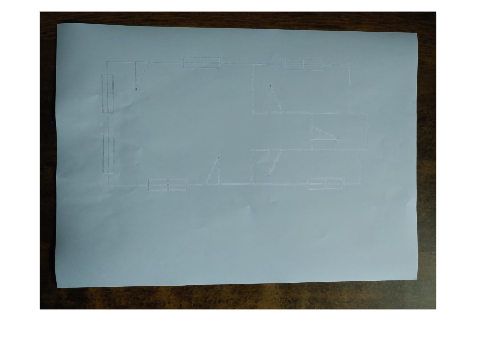


%--- Step 2: Erase all contents of the paper via Erosion and Dilation ---%
% Define a 5x5 square structuring element
se = strel('square', 5);

% Apply closing operation 3 times
J = maskedImage;
for k = 1:3
    J = imclose(J, se);
end
imshow(J)

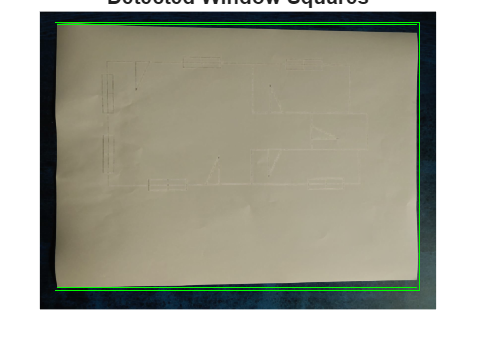

%--- Step 3: Run Square Detection Fxn to get bbox of  A4 paper ---%
A4Paper = detectWindowSquares(J);

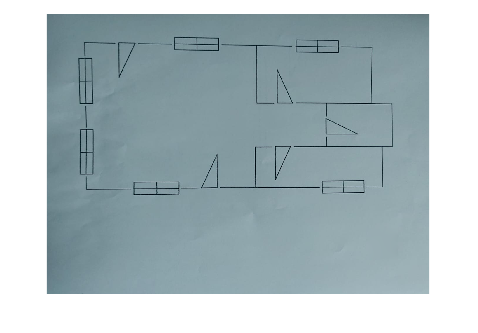

paper_standard = 1463504; % Typical area of an A4 paper
%Filter detected squares based on area to identify A4 paper 
% Increase tolerance if no squares are valid
validSquares = A4Paper(A4Paper(:,3).*A4Paper(:,4) > paper_standard * 0.5 & A4Paper(:,3).*A4Paper(:,4) < paper_standard * 1.6, :);
%--- Step 4: Crop the Original Image Without April Tag 'maskedImage' ---%
% Assuming validSquares is not empty, crop the original image based on the largest valid square
scale = -0.1; 
if ~isempty(validSquares)
    % Get the smallest valid square
    [~, idx] = min(validSquares(:, 3) .* validSquares(:, 4));
    cropBox = validSquares(idx, 1:4); % [x, y, width, height]
    % Scale crop box
    x = max(cropBox(1,1) - scale * cropBox(1,3) / 2, 0);
    y = max(cropBox(1,2) - scale * cropBox(1,4) / 2, 0);
    w = cropBox(1,3) * (1 + scale);
    h = cropBox(1,4) * (1 + scale);
    cropBox = [x, y, w, h];

    
    % Crop the image
    NoBackgroundImage = imcrop(maskedImage, cropBox);
    figure;
    imshow(NoBackgroundImage);
end

## Window Feauture Extraction Workflow Part 1

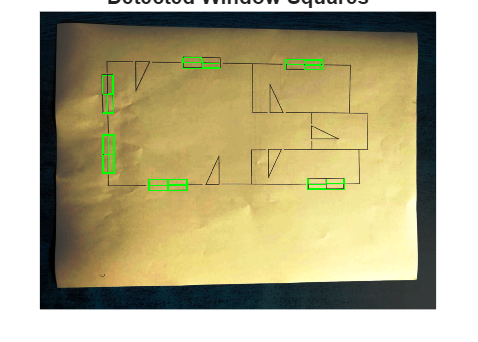

% ---Step 1: Apply Histogram Equalization on Original Image 'I' and Detect
RGB = maskedImage; % Red Blue Green channel image
equalized_RGB = histeq(RGB);
potentialWindows = detectWindowSquares(equalized_RGB);

% --- Step 2: Filter Out Boxes out of Crop Box ---
AreaOfcropBox = cropBox(1,3)*cropBox(1,4);
windowFeatures = [];
 %Create a logical mask for each row
mask = (potentialWindows(:,3) .* potentialWindows(:,4)) < AreaOfcropBox;

 % Use the mask to filter rows
windowFeatures = potentialWindows(mask, :);
windows_In_OrigImage = filterMainWindowBoxes(windowFeatures);
%--- Step 3: Transform windows_In_OrigImage from the orig image coordinates
%to coordinate system of NoBackground Image using cropBox

% Extract crop origin
x1 = cropBox(1);
y1 = cropBox(2);
w1 = cropBox(3);
h1 = cropBox(4);
    
    % Translate
newX = windows_In_OrigImage(:,1) - x1;
newY = windows_In_OrigImage(:,2) - y1;
newW = windows_In_OrigImage(:,3);
newH = windows_In_OrigImage(:,4);

% Clamp to cropped image boundaries
newX = max(newX, 0);
newY = max(newY, 0);
newW = min(newW, w1 - newX);
newH = min(newH, h1 - newY);
    
windows_In_CropImage = [newX, newY, newW, newH]; % Window marker bounding boxes in croped image

## Line Detection WorkFlow

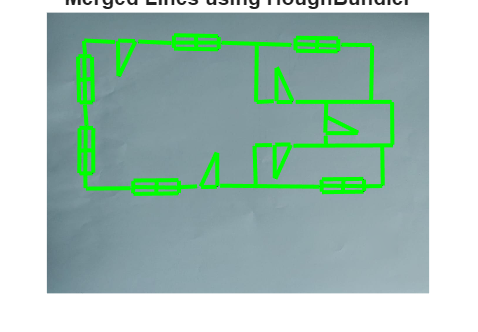

%NoBackgroundImage = uint8(NoBackgroundImage);                   % Ensure type is uint8
npImg = py.numpy.array(NoBackgroundImage); 

[lines_arr, img_rgb1] = detectAndDisplayLines(npImg);
min_distance = 10;
min_angle = 5;
lines_array = merge_groups(lines_arr, min_distance, min_angle);

% Process the lines_array for further analysis or visualization
imshow(NoBackgroundImage);
hold on;
title('Merged Lines using HoughBundler');
for i = 1:size(lines_array,1)
    x = [lines_array(i,1) lines_array(i,3)];
    y = [lines_array(i,2) lines_array(i,4)];
    plot(x, y, 'g-', 'LineWidth', 2);
end
hold off;

## Window Feauture Extraction Part 2

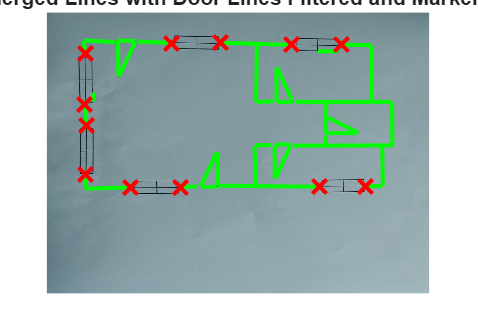

% --- Mask out all window markers and plot the precise positions of where
% windows will be installed 

imgWind = uint8(NoBackgroundImage);
masked_WindowImage = imgWind; % Variable to store image with filtered window markers
gap_max = 50.0;  % Maximum allowable distance to be considered a neighbor
window_marker = [];
all_window_lines = [];
all_window_lines1 = [];
scalew = 0.1;


scaled_windowBoxes = [];
% Scale all windowBoxes by 10 %
for i = 1:size(windows_In_CropImage, 1)
    % Extract coordinates and dimensions for the current door box
    x_box = windows_In_CropImage(i, 1);
    y_box = windows_In_CropImage(i, 2);
    w_box = windows_In_CropImage(i, 3);
    h_box = windows_In_CropImage(i, 4);
    x = max(x_box - scalew * w_box / 2, 0);
    y = max(y_box - scalew * h_box / 2, 0);
    w = w_box * (1 + scalew);
    h = h_box * (1 + scalew);
    scaled_windowBoxes = [scaled_windowBoxes; x, y, w, h];  % Store the adjusted door box dimensions
end
windows_In_CropImage = scaled_windowBoxes;

for i = 1:size(windows_In_CropImage, 1) % Loop over all window boxes
    % Filter out window marker lines
    bbox = windows_In_CropImage(i, :);
    % Filter out door Marker
    box = round(windows_In_CropImage(i, :));  % [x y w h]
    x1 = max(1, box(1));
    y1 = max(1, box(2));
    x2 = min(size(NoBackgroundImage,2), x1 + box(3) - 1);
    y2 = min(size(NoBackgroundImage,1), y1 + box(4) - 1);

    % Create mask for region
    mask = false(size(NoBackgroundImage,1), size(NoBackgroundImage,2));
    mask(y1:y2, x1:x2) = true;

        % Region fill (works on grayscale or per channel)
        if size(NoBackgroundImage, 3) == 3
            for c = 1:3
                channel = uint8(masked_WindowImage(:,:,c));
                filled = regionfill(channel, mask);
                masked_WindowImage(:,:,c) = filled;
            end
        else
            masked_WindowImage = regionfill(masked_WindowImage, mask);
        end

        % Detect lines in maskedImage
        masked_WindowImage = uint8(masked_WindowImage);                   % Ensure type is uint8
        npImg = py.numpy.array(masked_WindowImage);
        [lines_arr, img_rgb1] = detectAndDisplayLines(npImg);
        min_distance = 10;
        min_angle = 5;
        imageLines = merge_groups(lines_arr, min_distance, min_angle);
        filteredImage_lines = imageLines;

         % Crop Image and Extract window lines
        cropped_mat = cropImage(NoBackgroundImage, bbox, scalew);
        [~, pot_window_lines] = detectAndFilterLines(cropped_mat, bbox, filteredImage_lines, scalew);
        window_lines = filterSixWindowLines(pot_window_lines);

        all_window_lines1 = [all_window_lines1;window_lines;[0,0,0,0]];

        marker = WindowPlacementMarker(window_lines,filteredImage_lines);
        % Store the window marker and filtered lines for further processing
        window_marker = [window_marker; marker];
end

% --- Display Result ---
imshow(NoBackgroundImage);
hold on;
title('Merged Lines with Door Lines Filtered and Markers');
for i = 1:size(filteredImage_lines, 1)
    x = [filteredImage_lines(i,1) filteredImage_lines(i,3)];
    y = [filteredImage_lines(i,2) filteredImage_lines(i,4)];
    plot(x, y, 'g-', 'LineWidth', 2);
end
for i = 1:size(window_marker, 1)
    if window_marker(i,1) ~= 0 && window_marker(i,2) ~= 0
        plot(window_marker(i,1), window_marker(i,2), 'rx', 'MarkerSize', 10, 'LineWidth', 2);
    end
    if window_marker(i,3) ~= 0 && window_marker(i,4) ~= 0
        plot(window_marker(i,3), window_marker(i,4), 'rx', 'MarkerSize', 10, 'LineWidth', 2);
    end
end
hold off;

## Door Feauture Extraction

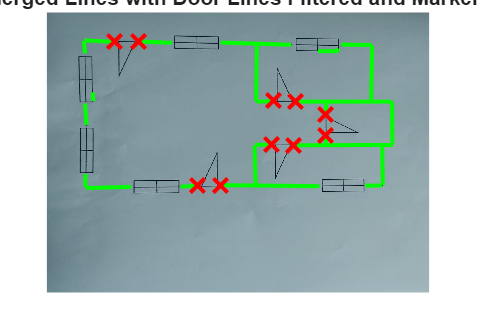

imageLines = filteredImage_lines; % Initialise imageLines which contain wall lines and door lines
masked_DoorImage = masked_WindowImage; % Initialize the variable which we want to hold image with no door markers
door_markers = [];

% ---Step 1: Perform Contrast Limited Adaptive Histogram Equalization.---
RGB = NoBackgroundImage;
LAB = rgb2lab(RGB);
% Scale values to the range expected by the adapthisteq function, [0 1].
L = LAB(:,:,1)/100;
% Perform CLAHE on the L channel. Scale the result to get back to the range used by the L*a*b* color space.
L = adapthisteq(L,'NumTiles',[8 8],'ClipLimit',0.005);
LAB(:,:,1) = L*100;
% Convert the resulting image back into the RGB color space.
Jpeg = lab2rgb(LAB);
Jpeg_uint8 = im2uint8(Jpeg);  % converts double [0,1] → uint8 [0,255]

% --- Step 2: Run Right Angle Triangle Detection Fxn on CLAHE filtered image---
doorBoxes = detectDoorMarker(Jpeg_uint8); % Right angle detection fxn

% --- Step 3: Filter out lines Representing Door markers---
scaled_doorBoxes = [];
% Scale all doorBoxes by 20 %
scale = 0.23;
for i = 1:size(doorBoxes, 1)
    % Extract coordinates and dimensions for the current door box
    x_box = doorBoxes(i, 1);
    y_box = doorBoxes(i, 2);
    w_box = doorBoxes(i, 3);
    h_box = doorBoxes(i, 4);
    x = max(x_box - scale * w_box / 2, 0);
    y = max(y_box - scale * h_box / 2, 0);
    w = w_box * (1 + scale);
    h = h_box * (1 + scale);
    scaled_doorBoxes = [scaled_doorBoxes; x, y, w, h];  % Store the adjusted door box dimensions
end
doorBoxes = scaled_doorBoxes;


for i = 1:size(doorBoxes, 1)
    bbox = doorBoxes(i, :);
    % Filter out door Marker
    box = round(doorBoxes(i, :));  % [x y w h]
    
        x1 = max(1, box(1));
        y1 = max(1, box(2));
        x2 = min(size(NoBackgroundImage,2), x1 + box(3) - 1);
        y2 = min(size(NoBackgroundImage,1), y1 + box(4) - 1);

        % Create mask for region
        mask = false(size(NoBackgroundImage,1), size(NoBackgroundImage,2));
        mask(y1:y2, x1:x2) = true;

        % Region fill (works on grayscale or per channel)
        if size(NoBackgroundImage, 3) == 3
            for c = 1:3
                channel = uint8(masked_DoorImage(:,:,c));
                filled = regionfill(channel, mask);
                masked_DoorImage(:,:,c) = filled;
            end
        else
            masked_DoorImage = regionfill(masked_DoorImage, mask);
        end

        % Detect lines in maskedImage
        masked_DoorImage = uint8(masked_DoorImage);                   % Ensure type is uint8
        npImg = py.numpy.array(masked_DoorImage);
        [lines_arr, img_rgb1] = detectAndDisplayLines(npImg);
        min_distance = 10;
        min_angle = 5;
        imageLines = merge_groups(lines_arr, min_distance, min_angle);
        filteredImage_lines = imageLines;
     
        % Extract line segments of door marker and find door placement
        % locations
        % Crop original image and detect lines
        cropped_mat = cropImage(NoBackgroundImage, bbox, scale);
        [~, door_lines] = detectAndFilterLines(cropped_mat, bbox, filteredImage_lines, scale);
    
    if ~isempty(door_lines)
        lineLengths = sqrt((door_lines(:,3) - door_lines(:,1)).^2 + (door_lines(:,4) - door_lines(:,2)).^2);
        [~, minIndex] = min(lineLengths);
        shortestLine = door_lines(minIndex, :);
        marker = detectSurroundingMarkers(shortestLine, filteredImage_lines, 10.0, 50.0);
        if any(marker)
            door_markers = [door_markers; marker];
        end
    end
end

%--- Step 4: Display Results ---%
% --- Display Result ---
imshow(NoBackgroundImage);
hold on;
title('Merged Lines with Door Lines Filtered and Markers');
for i = 1:size(filteredImage_lines, 1)
    x = [filteredImage_lines(i,1) filteredImage_lines(i,3)];
    y = [filteredImage_lines(i,2) filteredImage_lines(i,4)];
    plot(x, y, 'g-', 'LineWidth', 2);
end
for i = 1:size(door_markers, 1)
    if door_markers(i,1) ~= 0 && door_markers(i,2) ~= 0
        plot(door_markers(i,1), door_markers(i,2), 'rx', 'MarkerSize', 10, 'LineWidth', 2);
    end
    if door_markers(i,3) ~= 0 && door_markers(i,4) ~= 0
        plot(door_markers(i,3), door_markers(i,4), 'rx', 'MarkerSize', 10, 'LineWidth', 2);
    end
end
hold off;

## Translate All Results Back To Original Image Coordinates

% ---Step 1: List Out Items To Translate ---
% - door_markers: Precise door placement coordinates
% - filteredImage_lines: wall lines
% - window_marker: Precise window placement coordinates

% ---Step 2: Commence Translation using cropBox---
wall_lines_orig = translateCropCoorToOriginal(filteredImage_lines, cropBox);
door_markers_orig = translateCropCoorToOriginal(door_markers, cropBox);
window_markers_orig = translateCropCoorToOriginal(window_marker, cropBox);

## Virtual 3D Visual Of Building

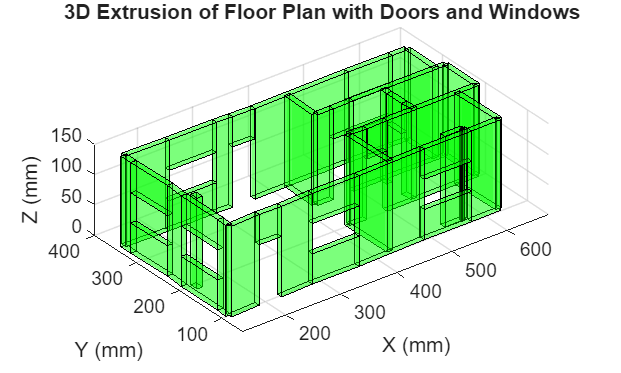

% --- Parameters ---
wallHeight = 150;        % mm
wallThickness = 10;      % mm
scaleFactor = 0.5;      % mm per pixel (adjust as needed)
% Heights for doors/windows
doorBase = (2/3)*wallHeight;
doorTop = wallHeight;
windowLowerHeight = (1/3)*wallHeight;
windowUpperBase = (2/3)*wallHeight;

% --- Scaled coordinates ---
scaleLines = @(L) L * scaleFactor;
lines = scaleLines(wall_lines_orig);
doors = scaleLines(door_markers_orig);
windows = scaleLines(window_markers_orig);

% --- Initialize storage ---
allVertices = [];
allFaces = [];
faceOffset = 0;

% --- Extrude Walls Fully ---
for i = 1:size(lines, 1)
    line = lines(i, :);
    vertices = createCuboidFromLine(line, wallHeight, wallThickness);

    % Add vertices and faces
    allVertices = [allVertices; vertices];
    faces = [1 2 3 4; 5 6 7 8; 1 5 6 2; 2 6 7 3; 3 7 8 4; 4 8 5 1] + faceOffset;
    allFaces = [allFaces; faces];
    faceOffset = faceOffset + 8;
end

% --- Doors: Upper 1/3 wall ---
for i = 1:size(doors, 1)
    door = doors(i, :);
    vertices = createCuboidFromLineAtHeight(door, doorBase, wallHeight - doorBase, wallThickness);

    allVertices = [allVertices; vertices];
    faces = [1 2 3 4; 5 6 7 8; 1 5 6 2; 2 6 7 3; 3 7 8 4; 4 8 5 1] + faceOffset;
    allFaces = [allFaces; faces];
    faceOffset = faceOffset + 8;
end

% --- Windows: Lower 1/3 ---
for i = 1:size(windows, 1)
    window = windows(i, :);
    vertices = createCuboidFromLineAtHeight(window, 0, windowLowerHeight, wallThickness);

    allVertices = [allVertices; vertices];
    faces = [1 2 3 4; 5 6 7 8; 1 5 6 2; 2 6 7 3; 3 7 8 4; 4 8 5 1] + faceOffset;
    allFaces = [allFaces; faces];
    faceOffset = faceOffset + 8;
end

% --- Windows: Upper 1/3 ---
for i = 1:size(windows, 1)
    window = windows(i, :);
    vertices = createCuboidFromLineAtHeight(window, windowUpperBase, windowLowerHeight, wallThickness);

    allVertices = [allVertices; vertices];
    faces = [1 2 3 4; 5 6 7 8; 1 5 6 2; 2 6 7 3; 3 7 8 4; 4 8 5 1] + faceOffset;
    allFaces = [allFaces; faces];
    faceOffset = faceOffset + 8;
end

% --- Visualization ---
figure;
patch('Vertices', allVertices, 'Faces', allFaces, ...
      'FaceColor', 'g', 'FaceAlpha', 0.3, 'EdgeColor', 'k');
axis equal;
xlabel('X (mm)'); ylabel('Y (mm)'); zlabel('Z (mm)');
title('3D Extrusion of Floor Plan with Doors and Windows');
view(3); grid on;

## Convert 2D Pixel Coordinates To Real World Coordinates

camExtrinsics = tagPose;
%--- Step 1: Convert wall lines from image Coordinates To World ----
% Initialize wall_lines_world
numLines = size(wall_lines_orig, 1);
wall_lines_world = zeros(numLines, 4);

% Loop over each wall line
for i = 1:numLines
    % Extract current line's endpoints as a 2x2 matrix
    line_2d = [wall_lines_orig(i,1:2); wall_lines_orig(i,3:4)];  % [x1 y1; x2 y2]
    
    % Initialize lines variable for this pair
    lines = zeros(2, 2);
    
    for j = 1:2
        imagePoint = line_2d(j, :);  % 1x2 point [x y]
        
        % Convert image point to world coordinates
        lines(j, :) = img2world2d(imagePoint, camExtrinsics, intrinsics);
    end
    
    % Flatten [x1 y1; x2 y2] -> [x1 y1 x2 y2]
    wall_lines_world(i, :) = reshape(lines.', 1, []);  % Transpose + reshape
end

%--- Step 2: Convert door marker positions from image to world
%coordinates ---

numLines = size(door_markers_orig, 1);
door_markers_world = zeros(numLines, 4);

% Loop over each door marker
for i = 1:numLines
    % Extract current line's endpoints as a 2x2 matrix
    line_2d = [door_markers_orig(i,1:2); door_markers_orig(i,3:4)];  % [x1 y1; x2 y2]
    
    % Initialize lines variable for this pair
    lines = zeros(2, 2);
    
    for j = 1:2
        imagePoint = line_2d(j, :);  % 1x2 point [x y]
        
        % Convert image point to world coordinates
        lines(j, :) = img2world2d(imagePoint, camExtrinsics, intrinsics);
    end
    
    % Flatten [x1 y1; x2 y2] -> [x1 y1 x2 y2]
    door_markers_world(i, :) = reshape(lines.', 1, []);  % Transpose + reshape
end

%--- Step 3: Convert window marker positions from image to world
%coordinates ---

numLines = size(window_markers_orig, 1);
window_markers_world = zeros(numLines, 4);

% Loop over each window marker
for i = 1:numLines
    % Extract current line's endpoints as a 2x2 matrix
    line_2d = [window_markers_orig(i,1:2); window_markers_orig(i,3:4)];  % [x1 y1; x2 y2]
    
    % Initialize lines variable for this pair
    lines = zeros(2, 2);
    
    for j = 1:2
        imagePoint = line_2d(j, :);  % 1x2 point [x y]
        
        % Convert image point to world coordinates
        lines(j, :) = img2world2d(imagePoint, camExtrinsics, intrinsics);
    end
    
    % Flatten [x1 y1; x2 y2] -> [x1 y1 x2 y2]
    window_markers_world(i, :) = reshape(lines.', 1, []);  % Transpose + reshape
end


## Augment Virtual Scene On Floor Plan

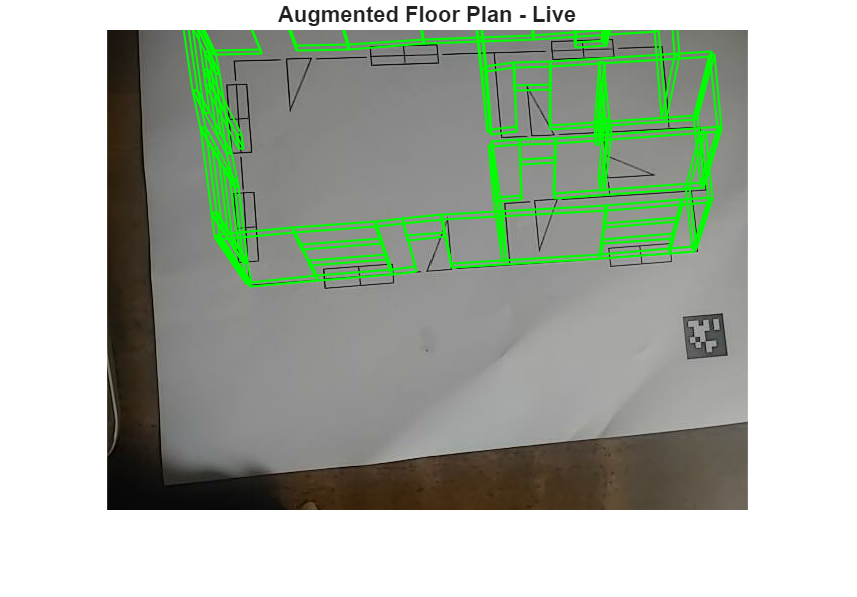

% --- Setup ---
cam = webcam('DroidCam Source 3');  % Initialize webcam
frameRate = 10;  % Adjust if needed
%tagSize = 43;    % mm
%tagFamily = "tag36h11";

% Load intrinsics (from Camera Calibrator App)
load("calibrationSession.mat");  % should contain 'cameraParams'


% Wall and floor plan properties
wallHeight = 50;      % mm
wallThickness = 2;    % mm

% Assume lines_world already computed from a reference image
% If not, detect lines in one frame and use img2world2d to get lines_world

% Create a figure to display
figure;

% Main loop
while true
    % --- Capture frame from webcam ---
    I = snapshot(cam);

    % --- Detect AprilTag and get pose ---
    try
        [~, ~, tagPose] = readAprilTag(I, tagFamily, intrinsics, tagSize);

        % Rotate Z axis if needed
        rotationAngles = [0 180 0];
        tform = rigidtform3d(rotationAngles, [0 0 0]);
        updatedR = tagPose.R * tform.R;
        tagPose = rigidtform3d(updatedR, tagPose.Translation);
    catch
        warning('Tag not found in this frame. Skipping...');
        imshow(I);
        title('No AprilTag Detected');
        pause(1/frameRate);
        continue;
    end

    % --- Project floor plan into image ---
    augmentedImage = projectExtrudedPlan(I, wall_lines_world, door_markers_world, window_markers_world, intrinsics, tagPose, wallHeight, wallThickness);

    % --- Display ---
    imshow(augmentedImage);
    title('Augmented Floor Plan - Live');
    drawnow;
    pause(1 / frameRate);  % Maintain real-time pace
end

## Test